# Service Ceiling Requirements

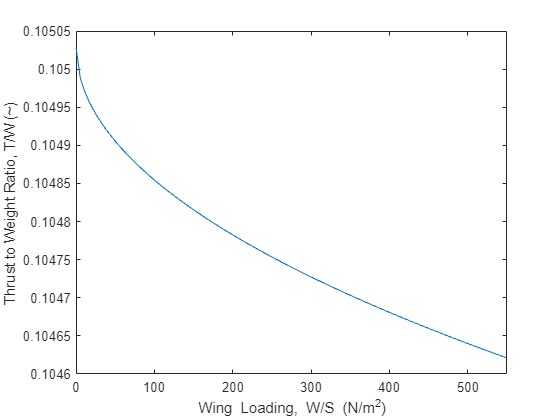

clc
clear all

L_Dmax = 46.5; % L/D max
A = 22.82; % Aspect ratio
e = 1; % Oswald's efficiency factor
eta_p = 0.8; % Prop efficiency, based on modern high efficient props
W2S = linspace(0,550,100); % Range of wing loadings in N/m^2
T_1 = 15; % Sea level temperature in C
sigma_7500 = 0.79826; % Density ratio at 7500 ft (mid point of climb) according to U.S. Standard Atmosphere 1976
% note to selfe, use atmoISA to find density ratio at altitude and divid by sea level
h = 14000; % Service ceiling in ft
h_abs = 15000; % Absolute ceiling in ft
RC_h = 100; % Rate of climb at altitude in ft/min, 100 ft/min chosen for service ceiling

% Find Rate of Climb at Sea Level
RC_0 = RC_h / (1 - (h/h_abs)); % Estimated rate of climb at sea level ft/min

% Find C_D0 to calculate C_LRCmax
C_Lmax = (pi * A * e) / (2 * L_Dmax); % Maximum lift coefficient
C_Dmax = 2 * (C_Lmax^2)/(pi * A * e); % Maximum drag coefficient
C_D0 = C_Dmax / 2; % Parasite drag coefficient

C_LRCmax = sqrt(3 * C_D0 * pi * A * e); % Maximum rate of climb lift coefficient

% Find C_DRCmax to find (C_L^3/2 / C_D)_max
C_DRCmax = 4 * C_D0; % Maximum rate of climb drag coefficient
%C_L32C_Dmax = (1.345 * (A * e)^(3/4)) / (C_D0^(1/4)); % C_L^3/2 / C_D
C_L32C_Dmax = (C_LRCmax^(3/2))/C_DRCmax;

% Find density ratio for mid point of climb + 10C
T_2 = (T_1 + 10 + 273.15); % Sea level temperature + 10C
sigma_ISA10 = (T_1 + 273.15) / (T_1 + 273.15); % Density ratio for ISA + 10C
sigma_7500_10 = sigma_ISA10 * sigma_7500; % Density ratio for 7500 ft + 10C

% Calculate RCP and substitute in power loading equation
RCP_EngU = RC_0/33000; % Rate of climb parameter hp/lbf
RCP = RCP_EngU * (745.7/4.45); % Rate of climb parameter in W/N

W2P = eta_p./(RCP + (sqrt(W2S)./(19 .* sqrt(sigma_7500_10) .* C_L32C_Dmax))); % Power loading N/W

figure(2)
plot(W2S,W2P)

xlabel("Wing Loading, W/S (N/m^2)");
ylabel("Power Loading, P/W (N/W)");

xlim([0, 550]);
%ylim([0,0.25]);